# Problem Solving Session 2

03/26/2021

## FNC 4.2.6

Fixed point iteration: $g(x) = 2x - 3x^2$

Discovered that

- $r = 1/3$ is a fixed point.

- $g'(1/3) = 0$ $\Longrightarrow$ FPI converges superlinearly.

Set-up

g = @(x) 2*x - 3*x.^2;
n = 10;
x = zeros(n,1);
err = zeros(n,1);

Iteration

r = 1/3;
x(1) = 0.1;
err(1) = abs( x(1) - r );
for k = 1:n-1
    x(k+1) = g( x(k) ); % FPI
    err(k+1) = abs( x(k+1) - r );
end

Plot the errors: 

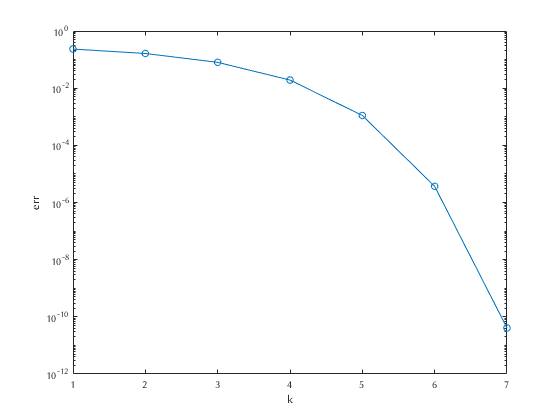

clf
semilogy(err, 'o-')
xlabel('k')
ylabel('err')